# **Praktikum 6 - Shift 2**

`31 Oktober 2023`

`Nama : Tesalonika Permatasari Hutapea`

`NIM  : 10121052`

## Runge-Kutta 4 Test

**Catatan : Apabila Anda belum didatangi oleh Asisten Praktikum untuk diuji, silakan kerjakan soal yang lain terlebih dahulu.**

**Nama Penguji : **(tulis nama penguji Anda di sini)

Misalkan diketahui Masalah Nilai Awal

### 
$$\begin{array}{l}
x^{\prime } =f\left(t,x,y\right)\\
y^{\prime } =g\left(t,x,y\right)
\end{array}$$


dengan $x\left(t_0 \right)=x_0$ dan $y\left(t_0 \right)=y_0$. Bangun fungsi `runge_kutta_2.m` yang menerima input $t_0 ,t_N ,N_t ,x_0 ,y_0 ,f,g$ dan mengeluarkan $t,x,y$ dengan keterangan variabel sebagai berikut :

- $t_0$ adalah waktu awal pengamatan solusi

- $t_N$ adalah waktu akhir pengamatan solusi

- $N_t$ adalah banyaknya subselang dari $\left\lbrack t_0 ,t_N \right\rbrack$

- $t$ adalah array yang berisi waktu $\left\lbrack t_0 ,t_N \right\rbrack$ yang dibagi menjadi $N_t$ subselang

- $x$ adalah array solusi $x\left(t\right)$ hasil Runge-Kutta 4

- $y$ adalah array solusi $y\left(t\right)$ hasil Runge-Kutta 4 

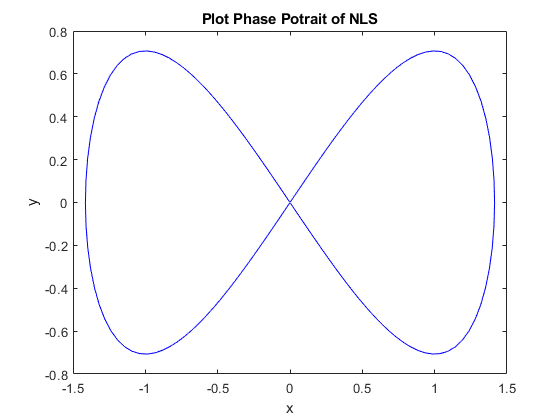

% Run Program di bawah untuk mengecek jawaban Anda
% ================================================
clear all ; clc ; close all
t0 = 0 ; 
tN = 15 ;
Nt = 200 ;
x0 = 0.001 ;
y0 = 0.001 ;
f = @(t,x,y) y ;
g = @(t,x,y) x-x.^3 ;
[t,x,y] = runge_kutta_2(t0,tN,Nt,x0,y0,f,g) ;
plot(x,y,'b',-x,y,'b')
title('Plot Phase Potrait of NLS')
xlabel('x')
ylabel('y')

## Nomor 1

*Untuk menjawab soal-soal di bawah ini, asumsikan Anda sudah melakukan Runge-Kutta 4 Test*

Diketahui suatu Sistem Persamaan Diferensial (SPD)

### 
$$x^{\prime } =x\left(3-x-4y\right)$$


### 
$$y^{\prime } =y\left(1-y-x\right)$$


dengan kondisi awal $x\left(t_0 \right)=x_0$ dan $y\left(t_0 \right)=y_0$

## Nomor 1A

Tentukan semua titik tetap/titik ekuilibrium dari sistem tersebut!

**Jawab :**

- Pertama untuk kasus x = 0 akan diperoleh persamaan untuk y' = 0 = y(1-y)  , maka jelas diperoleh titik tetapnya (0,1)

- Selanjutnya untuk kasus y = 0 akan diperoleh persamaan untuk x' = 0 = (3-y)  , maka jelas diperoleh titik tetapnya (3,0)

- Untuk kasus x = y = 0, jelas benar.

- Kemudian samakan persamaan 3 - x - 4y = 1 - y - x , sehingga diperoleh titik tetapnya (1/3, 2/3)

**(0,0) , (0,1) , (3,0) , (1/3, 2/3)**

## Nomor 1B

Tuliskan matriks Jacobi dari Sistem Persamaan Diferensial tersebut!

**Jawab :**

**Matriks Jacobinya diperoleh dengan menurunkan secara parsial kedua persamaan pada soal awal**


$$\left\lbrack \begin{array}{cc}
3-2x-4y & -4x\\
-y & 1-2y-x
\end{array}\right\rbrack$$


## Nomor 1C

Perhatikan bahwa matriks Jacobi yang dihasilkan bergantung pada nilai $\left(x,y\right)$. Matriks Jacobi ini dapat digunakan untuk memeriksa kestabilan semua titik tetap sistem tersebut. Misalkan terdapat $n$ titik tetap, bangun matriks `eig_J `berukuran $2\times n$ yang berisi nilai-nilai eigen semua titik tetapnya!

% Ketik jawaban Anda di bawah garis
% =================================
J = @(x,y) [3 - 2*x - 4*y , -4*x
           -y , 1-2*y-x];
           
x = [0,0,3,1/3];
y = [0,1,0,2/3];

for i = 1:4
    eig_values(:,i) = eig(J(x(i),y(i)));
end
eig_values

eig_values =     1.0000   -1.0000   -3.0000    0.4574
    3.0000   -1.0000   -2.0000   -1.4574


## Nomor 1D

Gunakan fungsi `runge_kutta_2.m `yang sudah Anda bangun untuk menyelesaikan Sistem Persamaan Diferensial tersebut dengan nilai-nilai awal $\left(x_0 ,y_0 \right)$ berikut : $\left(0\ldotp 3342,0\ldotp 662\right),\left(0\ldotp 3325,0\ldotp 6672\right),\left(0\ldotp 01,0\ldotp 16\right),\left(3,0\ldotp 7\right),\left(3,2\ldotp 5\right),\left(0\ldotp 01,0\ldotp 2\right)$ dengan selang waktu pengamatan $\left\lbrack 0,20\right\rbrack$ yang dipartisi sebanyak $300$ subselang! Setelah itu, lakukan plot $y$ terhadap $x$ dan tandai seluruh titik tetapnya!

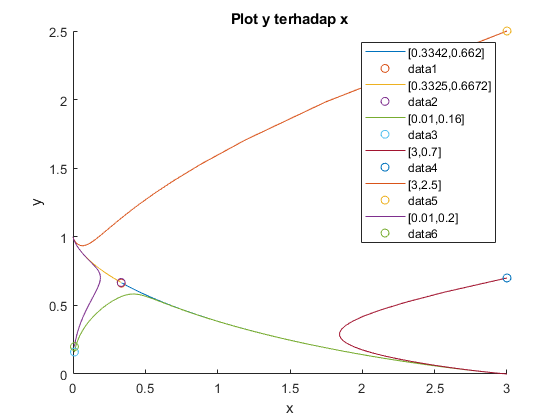

% Ketik jawaban Anda di bawah garis
% =================================
clear all ; clc ; close all
pair = [[0.3342,0.3325] , [0.01,3] , [3,0.01] , [0.662,0.6672] , [0.16,0.7] , [2.5,0.2]];
pair = reshape(pair,[6,2]);
for i = 1:6
    x0 = pair(i,1);
    y0 = pair(i,2);
    f = @(t,x,y) x*(3-x-4*y) ;
    g = @(t,x,y) y*(1-y-x) ;
    [t,x,y] = runge_kutta_2(0,20,300,x0,y0,f,g) ;
    hold on
    plot(x,y,'DisplayName','['+string(pair(i,1))+','+string(pair(i,2))+']')
    plot(x0,y0,"o")
    
end
hold off
title('Plot y terhadap x')
xlabel('x')
ylabel('y')
legend

## Nomor 1E

Buatlah subplot sebanyak **2 baris dan 3 kolom** dengan masing-masing subplot berisi solusi $x$ dan $y$ terhadap $t$ pada Sistem Persamaan Diferensial tersebut. Gunakan 6 buah nilai awal dari **Nomor 1D**!

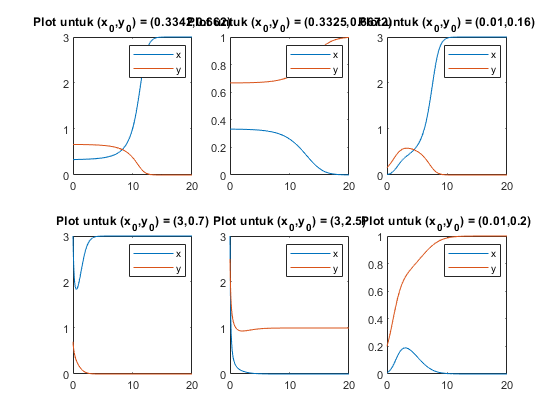

% Ketik jawaban Anda di bawah garis
% =================================
clear all ; clc ; close all
pair = [[0.3342,0.3325] , [0.01,3] , [3,0.01] , [0.662,0.6672] , [0.16,0.7] , [2.5,0.2]];
pair = reshape(pair,[6,2]);
for i = 1:6
    x0 = pair(i,1);
    y0 = pair(i,2);
    f = @(t,x,y) x*(3-x-4*y) ;
    g = @(t,x,y) y*(1-y-x) ;
    [t,x,y] = runge_kutta_2(0,20,300,x0,y0,f,g) ;
    subplot(2,3,i)
    plot(t,x)
    hold on
    plot(t,y)
    hold on
    title('Plot untuk (x_0,y_0) = ('+string(pair(i,1))+','+string(pair(i,2))+')')
    legend("x", "y")
end
hold off

## Nomor 1F

Andaikan sistem tersebut menceritakan kondisi kompetisi antara dua hewan, yaitu kelinci dan domba dengan $x\left(t\right)$ menyatakan banyaknya kelinci dan $y\left(t\right)$ menyatakan banyaknya domba setiap waktu. Pilih 3 dari 6 kondisi awal pada **Nomor 1E** dan berikan komentar masing-masing terkait keberadaan kelinci dan domba untuk waktu yang cukup lama!

**Jawab :**

**Misalkan populasi awal (x,y) dengan x merepresentasikan populasi awal kelinci dan y merepresentasikan populasi awal domba.**

- Untuk kondisi awal $\left(0\ldotp 3342\;,\;0\ldotp 662\right),\;$pada kasus awal keduanya akan saling berkompetisi untuk bertahan hidup. Namun pada saat waktu tertentu, populasi domba akan sangat naik menyebabkan kompetisi akan semakin tinggi sehingga populasi kelinci otomatis akan semakin berkurang. Lama kelamaan, populasi kelinci akan punah karena tidak mendapat makanan.

- Untuk kondisi awal $\left(3\;,0\ldotp 7\right)$ di kasus awal, populasi kelinci sangat banyak bila dibandingkan dengan domba. Di awal populasi kelinci akan sedikit berkurang karena ada kompetisi untuk mencari makanan dengan domba namun untuk waktu selanjutnya, populasi akan meningkat dan bertahan dalam jumlah yang banyak karena populasi domba sudah punah dikarenakan kompetisi makanannya sudah sulit.

- Untuk kondisi awal $\left(0\ldotp 01\;,0\ldotp 2\right)$ pada kondisi awal populasi keduanya tidak terlalu jauh berbeda dan tidak terlalu tinggi sehingga keduanya sama sama bisa meingkat populasinya. Namun ketika populasi domba sudah semakin cepat bertumbuh, menyebabkan kelinci harus semakin bersaing untuk mendapatkan makanannya. Sehingga lama- kelamaan populasi kelinci akan semakin berkurang hingga akhirnya punah. 

Dari ketiga kondisi awal yang sudah dipilih, terlihat kondisi akhir yang sama di mana salah satunya akan punah dan yang lainnya akan terus bertumbuh sampai di titik ekulibriumnya.